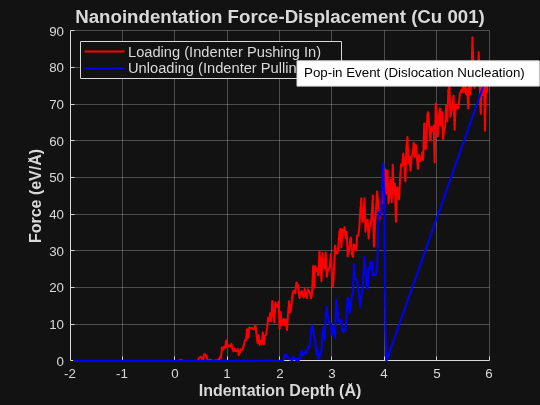

% Use readmatrix to bypass the text header
data = readmatrix('force_depth.txt');

% Find the point of maximum indentation depth (the turnaround point)
[~, max_idx] = max(data(:, 1));

% Split the data into Loading and Unloading phases
depth_load = data(1:max_idx, 1);
force_load = data(1:max_idx, 2);

depth_unload = data(max_idx:end, 1);
force_unload = data(max_idx:end, 2);

% Plot the separated curves with different colors
figure; hold on;
plot(depth_load, force_load, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Loading (Indenter Pushing In)');
plot(depth_unload, force_unload, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Unloading (Indenter Pulling Out)');

xlabel('Indentation Depth (Å)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Force (eV/Å)', 'FontSize', 12, 'FontWeight', 'bold');
title('Nanoindentation Force-Displacement (Cu 001)', 'FontSize', 14);

% Add the legend in the top left
legend('Location', 'northwest', 'FontSize', 11);
grid on;

% Add the pop-in annotation pointing near the drop
annotation('textbox', [0.55 0.75 0.3 0.1], 'String', ...
    'Pop-in Event (Dislocation Nucleation)', ...
    'FitBoxToText', 'on', 'BackgroundColor', 'white', 'Color', 'black');
hold off;